% ID number: 2021200687
% Name:      唐金峰
% Date:      Nov 25, 2021
load TestData_KayMSE.mat

x = TestData_KayMSE;

## Autocorrelation Method

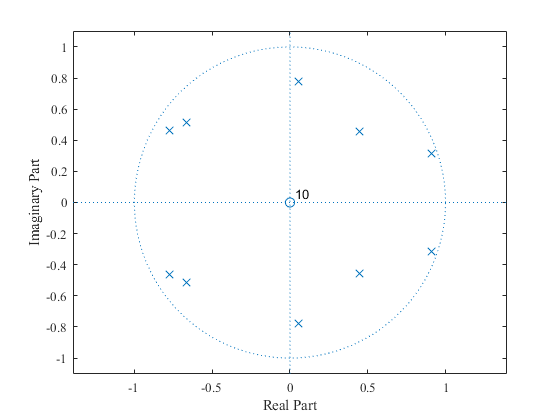

rxx = zeros(12,1);
rxx(1) = dot(x,x);
for i = 1 : length(rxx)-1
    x_lag  = circshift(x,-i);
    x_lag(end-i+1:end) = 0;
    rxx(i+1)= dot(x,x_lag);
end
rxx = rxx./length(x);
rxx_complex = [conj(flip(rxx(2:end))); rxx];
% figure; stem(-length(rxx)+1:length(rxx)-1,rxx_complex); title('Correlagram')
ar10 = -toeplitz(rxx(1:10)) \ rxx(2:11);
AR = arima(10,0,0);
AR.Constant = 0;
AR.Variance = rxx(1)+ dot(ar10', rxx(2:11));
AR.AR = num2cell(ar10',10);
figure; zplane(1, [1 cell2mat(AR.AR)]);
get(gca,'fontname'); set(gca,'fontname','Times New Roman')

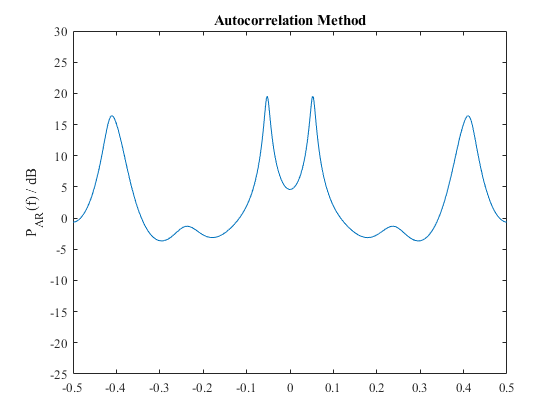

A = 1;
f = linspace(-1/2,1/2,800);
for fk = 1:10
    A = A + ar10(fk)*exp(-1j*2*pi*f*fk);
end
A = abs(A).^2;
par = AR.Variance./A;
figure; plot(f, pow2db(par))
ylabel 'P_{AR}(f) / dB'
title 'Autocorrelation Method'
ylim([-25 30])
get(gca,'fontname'); set(gca,'fontname','Times New Roman')

## Covariance Method

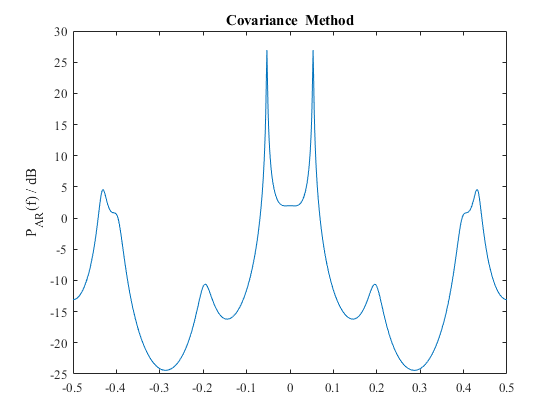

cxx = zeros(10,10);
for m =1:10
    for n = 1:10
        xjm = x(11-m:end-m);
        xkm = x(11-n:end-n);
        cxx(m,n) = 1/(length(x)-10) * dot(xjm, xkm);
    end
end
cx0 = zeros(10,1);
for m =1:10
    cx0(m) = 1/(length(x)-10) * dot(x(11-m:end-m), x(11:end));
end
ar10 = -cxx \ cx0;

A = 1;
f = linspace(-1/2,1/2,800);
for fk = 1:10
    A = A + ar10(fk)*exp(-1j*2*pi*f*fk);
end
A = abs(A).^2;
sigma_2 = 1/(length(x)-10)* dot(x(11:end),x(11:end))+ dot(ar10', cx0);
par = sigma_2./A;
figure; plot(f, pow2db(par))
ylabel 'P_{AR}(f) / dB'
title 'Covariance  Method'
ylim([-25 30])
get(gca,'fontname'); set(gca,'fontname','Times New Roman')

% AR = arima(10,0,0);
% AR.Constant = 0;
% AR.Variance = sigma_2;
% AR.AR = num2cell(ar10',10);
% figure; zplane(1, [1 ar10']);
% get(gca,'fontname'); set(gca,'fontname','Times New Roman')

## Modified Covariance Method

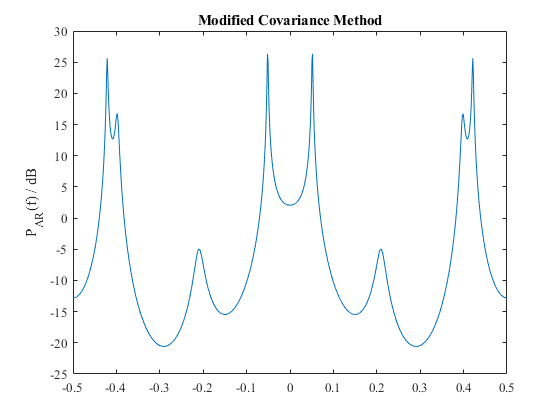

cxx = zeros(10,10);
for m =1:10
    for n = 1:10
        xjm = x(11-m:end-m);
        xkm = x(11-n:end-n);
        xjp = x(1+m:end-10+m);
        xkp = x(1+n:end-10+n);
        cxx(m,n) = 0.5/(length(x)-10) *( dot(xjm, xkm)+ dot(xjp, xkp) );
    end
end
cx0 = zeros(10,1);
for m =1:10
    xjm = x(11-m:end-m);
    xkm = x(11:end);
    xjp = x(1+m:end-10+m);
    xkp = x(1:end-10);
    cx0(m) = 0.5/(length(x)-10) *( dot(xjm, xkm)+ dot(xjp, xkp) );
end
ar10 = -cxx \ cx0;

A = 1;
f = linspace(-1/2,1/2,800);
for fk = 1:10
    A = A + ar10(fk)*exp(-1j*2*pi*f*fk);
end
A = abs(A).^2;
c00 = 0.5/(length(x)-10)* (dot(x(11:end),x(11:end)) + dot(x(1:end-10), x(1:end-10)));
sigma_2 = c00 + dot(ar10', cx0);
par = sigma_2./A;
figure; plot(f, pow2db(par))
ylabel 'P_{AR}(f) / dB'
title 'Modified Covariance Method'
ylim([-25 30])
get(gca,'fontname'); set(gca,'fontname','Times New Roman')

% AR = arima(10,0,0);
% AR.Constant = 0;
% AR.Variance = sigma_2;
% AR.AR = num2cell(ar10',10);
% figure; zplane(1, [1 ar10']);
% get(gca,'fontname'); set(gca,'fontname','Times New Roman')

## Burg Method

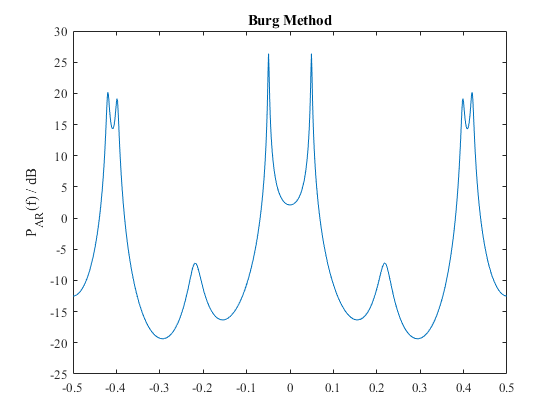

rho = dot(x,x)/length(x);
e_f = x; e_f(1) = 0;
e_b = x; e_b(end) = 0;
for k = 1:10
    kk = -2*dot(e_b(k:end-1),e_f(k+1:end)) / (dot(e_f(k+1:end),e_f(k+1:end)) + ...
        dot(e_b(k:end-1),e_b(k:end-1)));
    kkk = -2*dot(e_b(k:end-1),e_f(k+1:end)) / (dot(e_f,e_f) + ...
        dot(e_b,e_b));
    assert((kk-kkk)<1e-5)
    rho = (1-kk^2)*rho;
    if k==1
        ak = kk;
    else
        akp = zeros(1,k);
        for i=1:k-1
            akp(i) = ak(i) + kk*conj(ak(k-i));
        end
        akp(k)=kk;
        ak = akp;
    end
    ef = e_f(k+2:end) + kk*e_b(k+1:end-1); 
    eb= e_b(k:end-2) + conj(kk)*e_f(k+1:end-1);
    e_f(k+2:end) = ef; e_f(k+1) = 0;
    e_b(k+1:end-1) = eb; e_b(k)=0;
end
A = 1;
f = linspace(-1/2,1/2,800);
for fk = 1:10
    A = A + ak(fk)*exp(-1j*2*pi*f*fk);
end
A = abs(A).^2;
par = rho./A;
figure; plot(f, pow2db(par))
ylabel 'P_{AR}(f) / dB'
title 'Burg Method'
ylim([-25 30])
get(gca,'fontname'); set(gca,'fontname','Times New Roman')

% AR = arima(10,0,0);
% AR.Constant = 0;
% AR.Variance = sigma_2;
% AR.AR = num2cell(ar10',10);
% figure; zplane(1, [1 ar10']);
% get(gca,'fontname'); set(gca,'fontname','Times New Roman')

%% Matlab 直接估计参数
% AR = arima(10,0,0);
% AR.Constant = 0;
% AR.Variance = 1;
% AR = estimate(AR,x');
% figure
% [hz,hp] = zplane(1, [1 cell2mat(AR.AR)]);

## 仿真举例

% AR4 = arima();
% AR4.Constant = 0;
% AR4.Variance = 1;
% % AR.AR = { 0.0 0.49};
% [hz,hp] = zplane(1, [1 cell2mat({-1.352 1.338 -0.662 0.240})]);
% AR4.AR = {-1.352 1.338 -0.662 0.240};
% AR4.AR = {-2.760 3.809 -2.654 0.924};

clear;
% ar_real = [-1.352 1.338 -0.662 0.240];
ar_real = [-2.760 3.809 -2.654 0.924];
u = randn(50,256);
xlib = zeros(50,256);
f= linspace(0,1/2,400);
PSD  = repmat(f,50,1);
xlib(:,1) =u(:,1);
xlib(:,2) =-ar_real(1)*xlib(:,1) + u(:,2);
xlib(:,3) =-ar_real(1)*xlib(:,2) -ar_real(2)*xlib(:,1)+ u(:,3);
xlib(:,4) =-ar_real(1)*xlib(:,3) -ar_real(2)*xlib(:,2)- ...
    ar_real(3)*xlib(:,1)+ u(:,4);
for l= 5: 256
    xlib(:,l) = -ar_real(1)*xlib(:,l-1) -ar_real(2)*xlib(:,l-2)- ...
    ar_real(3)*xlib(:,l-3) -ar_real(4)*xlib(:,l-4)+ u(:,l);
end
A = 1;
for fk = 1:4
    A = A + ar_real(fk)*exp(-1j*2*pi*f*fk);
end
A = abs(A).^2;
par_real = 1./A;

## Autocorrelation Method

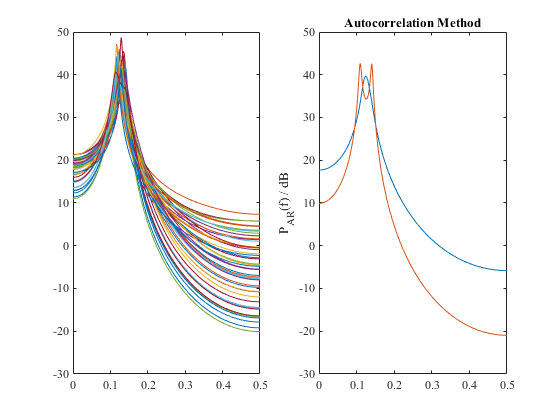

figure;subplot(121)
for number =1:50
    x = xlib(number,:);
    rxx = zeros(12,1);
    rxx(1) = dot(x,x);
    for i = 1 : length(rxx)-1
        x_lag  = circshift(x,-i);
        x_lag(end-i+1:end) = 0;
        rxx(i+1)= dot(x,x_lag);
    end
    rxx = rxx./length(x);
    rxx_complex = [conj(flip(rxx(2:end))); rxx];
    ar4 = -toeplitz(rxx(1:4)) \ rxx(2:5);
    sigma_2 = rxx(1)+ dot(ar4', rxx(2:5));
    A = 1;
    for fk = 1:4
        A = A + ar4(fk)*exp(-1j*2*pi*f*fk);
    end
    A = abs(A).^2;
    par = sigma_2./A;
    plot(f, pow2db(par))
    PSD(number,:) = pow2db(par);
    hold on
end
get(gca,'fontname'); set(gca,'fontname','Times New Roman')
subplot(122)
plot(f, mean(PSD,1))
get(gca,'fontname'); set(gca,'fontname','Times New Roman')
hold on
plot(f,pow2db(par_real))
ylabel 'P_{AR}(f) / dB'
title 'Autocorrelation Method'

## Covariance Method

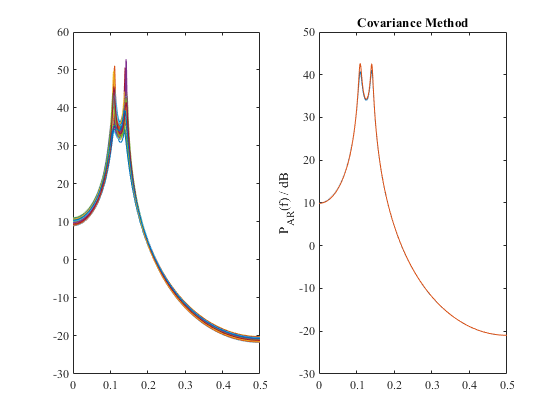

figure;
subplot(121)
for number =1:50
    x = xlib(number,:);
    cxx = zeros(4,4);
    for m =1:4
        for n = 1:4
            xjm = x(5-m:end-m);
            xkm = x(5-n:end-n);
            cxx(m,n) = 1/(length(x)-4) * dot(xjm, xkm);
        end
    end
    cx0 = zeros(4,1);
    for m =1:4
        cx0(m) = 1/(length(x)-4) * dot(x(5-m:end-m), x(5:end));
    end
    ar4 = -cxx \ cx0;
    sigma_2 = 1/(length(x)-4)* dot(x(5:end),x(5:end))+ dot(ar4', cx0);
    A = 1;
    for fk = 1:4
        A = A + ar4(fk)*exp(-1j*2*pi*f*fk);
    end
    A = abs(A).^2;
    par = sigma_2./A;
    plot(f, pow2db(par))
    PSD(number,:) = pow2db(par);
    hold on
end
get(gca,'fontname'); set(gca,'fontname','Times New Roman')
subplot(122)
plot(f, mean(PSD,1))
get(gca,'fontname'); set(gca,'fontname','Times New Roman')
hold on
plot(f,pow2db(par_real))
ylabel 'P_{AR}(f) / dB'
title 'Covariance Method'

## Modified Covariance Method

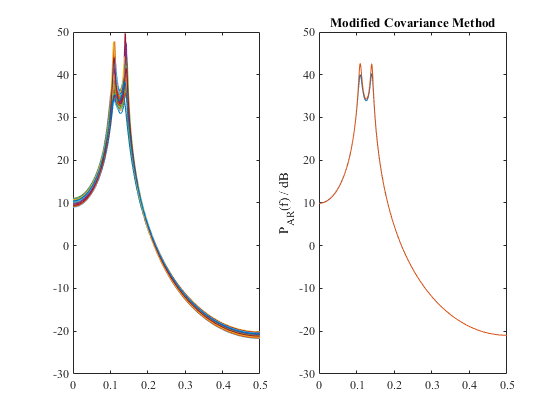

figure;
subplot(121)
for number =1:50
    x = xlib(number,:);
    cxx = zeros(4,4);
    for m =1:4
        for n = 1:4
            xjm = x(5-m:end-m);
            xkm = x(5-n:end-n);
            xjp = x(1+m:end-4+m);
            xkp = x(1+n:end-4+n);
            cxx(m,n) = 0.5/(length(x)-4) *( dot(xjm, xkm)+ dot(xjp, xkp) );
        end
    end
    cx0 = zeros(4,1);
    for m =1:4
        xjm = x(5-m:end-m);
        xkm = x(5:end);
        xjp = x(1+m:end-4+m);
        xkp = x(1:end-4);
        cx0(m) = 0.5/(length(x)-4) *( dot(xjm, xkm)+ dot(xjp, xkp) );
    end
    ar4 = -cxx \ cx0;
    c00 = 0.5/(length(x)-4)* (dot(x(5:end),x(5:end)) + dot(x(1:end-4), x(1:end-4)));
    sigma_2 = c00 + dot(ar4', cx0);
    A = 1;
    for fk = 1:4
        A = A + ar4(fk)*exp(-1j*2*pi*f*fk);
    end
    A = abs(A).^2;
    par = sigma_2./A;
    plot(f, pow2db(par))
    PSD(number,:) = pow2db(par);
    hold on
end
get(gca,'fontname'); set(gca,'fontname','Times New Roman')
subplot(122)
plot(f, mean(PSD,1))
get(gca,'fontname'); set(gca,'fontname','Times New Roman')
hold on
plot(f,pow2db(par_real))
ylabel 'P_{AR}(f) / dB'
title 'Modified Covariance Method'

## Burg Method

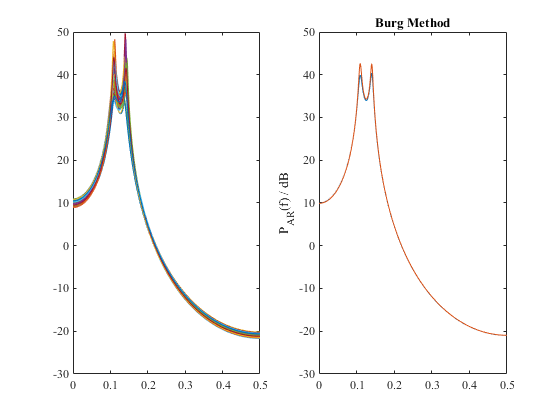

figure;
subplot(121)
for number =1:50
    x = xlib(number,:);
    rho = dot(x,x)/length(x);
    e_f = x; e_f(1) = 0;
    e_b = x; e_b(end) = 0;
    for k = 1:4
        kk = -2*dot(e_b(k:end-1),e_f(k+1:end)) / (dot(e_f(k+1:end),e_f(k+1:end)) + ...
            dot(e_b(k:end-1),e_b(k:end-1)));
        rho = (1-kk^2)*rho;
        if k==1
            ak = kk;
        else
            akp = zeros(1,k);
            for i=1:k-1
                akp(i) = ak(i) + kk*conj(ak(k-i));
            end
            akp(k)=kk;
            ak = akp;
        end
        ef = e_f(k+2:end) + kk*e_b(k+1:end-1); 
        eb= e_b(k:end-2) + conj(kk)*e_f(k+1:end-1);
        e_f(k+2:end) = ef; e_f(k+1) = 0;
        e_b(k+1:end-1) = eb; e_b(k)=0;
    end
    A = 1;
    for fk = 1:4
        A = A + ak(fk)*exp(-1j*2*pi*f*fk);
    end
    A = abs(A).^2;
    par = rho./A;
    plot(f, pow2db(par))
    PSD(number,:) = pow2db(par);
    hold on
end
get(gca,'fontname'); set(gca,'fontname','Times New Roman')
subplot(122)
plot(f, mean(PSD,1))
get(gca,'fontname'); set(gca,'fontname','Times New Roman')
hold on
plot(f,pow2db(par_real))
ylabel 'P_{AR}(f) / dB'
title 'Burg Method'